data =readtable('Log2k.csv');


[a1WaitTimes,a1mean]=meanWaitingTime(data,0);
[bWaitTimes,bmean]=meanWaitingTime(data,1);
[a2WaitTimes,a2mean]=meanWaitingTime(data,2);


[a1Upper,a1Lower]=confidenceInterval(a1WaitTimes)

mu = 0.1098

a1Upper = 0.1110

a1Lower = 0.1085

[bUpper,bLower]=confidenceInterval(bWaitTimes)

mu = 0.1089

bUpper = 0.1102

bLower = 0.1076

[a2Upper,a2Lower]=confidenceInterval(a2WaitTimes)

mu = 0.1098

a2Upper = 0.1110

a2Lower = 0.1086

creation=data(strcmp(data{:,1}, 'Creation') & (data{:,5}==0), 2);
arrive=data(strcmp(data{:,1}, 'Ambulance at Patient') & (data{:,5}==0), 2);

timeBeforePickup=arrive{:,1}-creation{:,1};
a1WaitedMoreThanFifteen=length(timeBeforePickup(timeBeforePickup>0.25))

a1WaitedMoreThanFifteen = 49

percentageofA1=a1WaitedMoreThanFifteen/size(creation,1)

percentageofA1 = 0.0082

[a1waitUpper,a1waitLower]=confidenceInterval(timeBeforePickup)

mu = 0.0595

a1waitUpper = 0.0605

a1waitLower = 0.0585

shiftchanges=data(strcmp(data{:,1},'Crew Change'),[2,4]);

shiftchanges = 10098×2 table
     Var2           Var4      
    ______    ________________

    6.8333    {'Ambulance 1' }
    6.8333    {'Ambulance 2' }
    6.8333    {'Ambulance 3' }
    6.8333    {'Ambulance 4' }
    6.8333    {'Ambulance 5' }
    6.8333    {'Ambulance 6' }
    6.8333    {'Ambulance 7' }
    6.8333    {'Ambulance 8' }
    6.8333    {'Ambulance 9' }
    6.8333    {'Ambulance 10'}
    6.8333    {'Ambulance 11'}
    6.8333    {'Ambulance 12'}
    6.8333    {'Ambulance 13'}
    6.8333    {'Ambulance 14'}
    6.8333    {'Ambulance 15'}
    6.8333    {'Ambulance 17'}


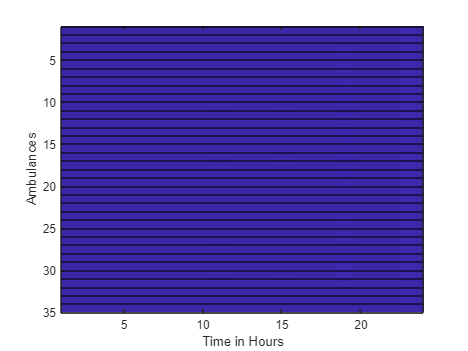

makeFig(shiftchanges,24)

function [waitTime,res]=meanWaitingTime(d,t)
    creation=d(strcmp(d{:,1}, 'Creation') & (d{:,5}==t), 2);
    arrive=d(strcmp(d{:,1}, 'Ambulance at Patient') & (d{:,5}==t), 2);
    process=d(strcmp(d{:,1}, 'Patient Processed') & (d{:,5}==t), 2);
    
    delay=arrive{:,1}-creation{:,1};
    serviceTime=process{:,1}-arrive{:,1};
    waitTime=delay+serviceTime;
    res=sum(waitTime)/length(waitTime);
end

function []=makeFig(sc,maxTime)
    labels=(sc{:,2});
    
    for i=1:length(labels)
        v=strsplit(labels{i} ," ");
        sc(i,2)=v(2);
        sc(i,1)=table(round(sc{i,1}));
    end

    sched=zeros(35,maxTime);
    for i=1:size(sc,1)
        sched(cellfun(@str2num,sc{i,2}),sc{i,1})=sc{i,1};
    end

    figure
    image(sched,'CDataMapping','scaled')
    ylabel('Ambulances')
    xlabel("Time in Hours")
    
    for i=1:35
        yline(i,"Color","black")
    end
%{
    for i=1:maxTime
            xline(i,"Color","black")
    end
%}
    
    axis([1 maxTime 1 35])


end


function [upper,lower]= confidenceInterval(d)
    
    n=length(d);
    mu=sum(d)/n
    s= (sum((d-mu).^2)/(n-1))^(.5);
    upper=mu+(1.96)*(s/(n)^(.5));
    lower=mu-(1.96)*(s/(n)^(.5));
end